clear

addpath("..\..\algorithms\")

#### Read MFD data

[delta_B, f, defects] = LoadSaveData('data/delta-B_circ2mmx4.txt');

#### Load $\Phi$

load('data\Phi.mat', 'Phi','freqs','voxels_center')

[~,k] = ismember(f, freqs);
Phi = Phi(:,:,k);

xylim = 15e-3;
mask = -xylim < voxels_center(1,:) & voxels_center(1,:) < xylim & ...
       -xylim < voxels_center(2,:) & voxels_center(2,:) < xylim & ...
                                     voxels_center(3,:) > -2.1e-3;

Phi = Phi(:, mask, :);
voxels_center = voxels_center(:, mask);

y = delta_B;

Phi = cat(3, real(Phi),imag(Phi));
y   = cat(3, real(y),  imag(y)  );

clear freqs delta_B k xylim mask

#### Reconstruction

a = 0.0500

b = 0.1000

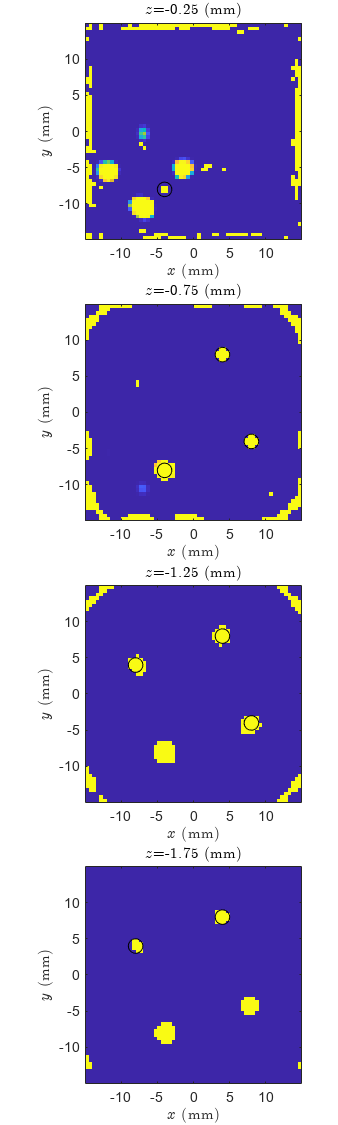

a = 0.0500

b = 0.1500

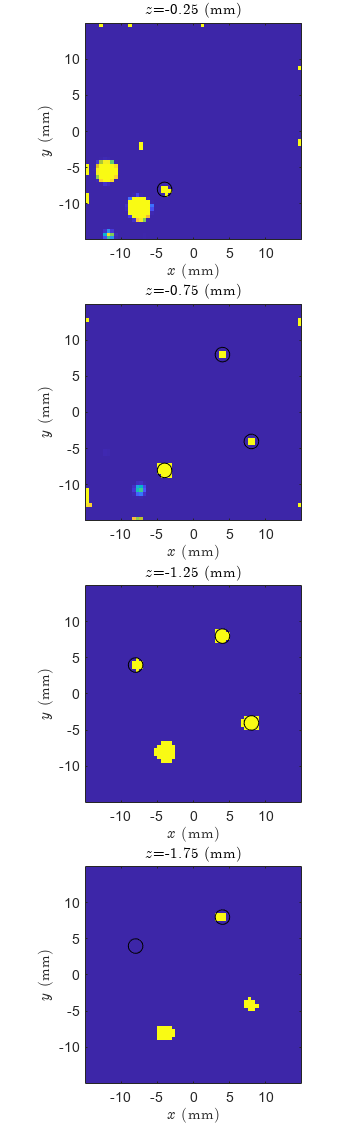

a = 0.0500

b = 0.2000

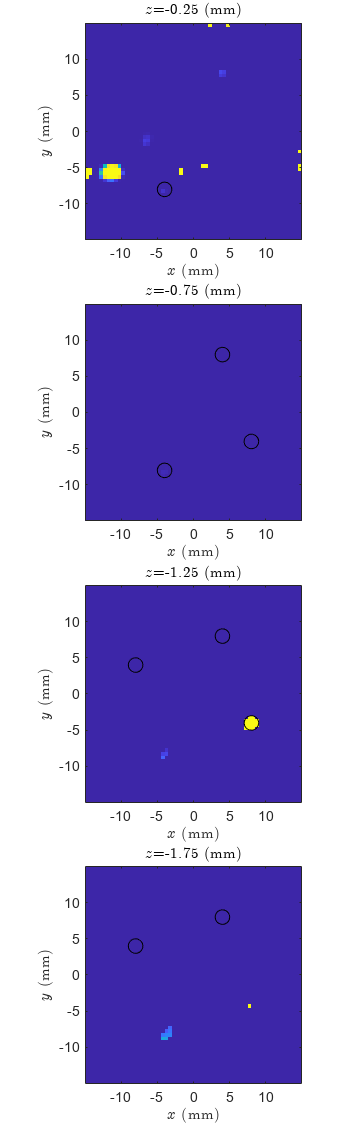

a = 0.0500

b = 0.2500

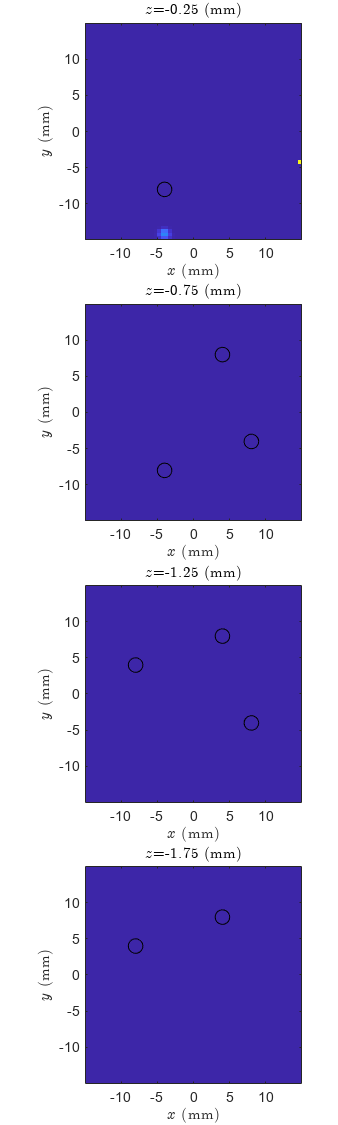

a = 0.0500

b = 0.3000

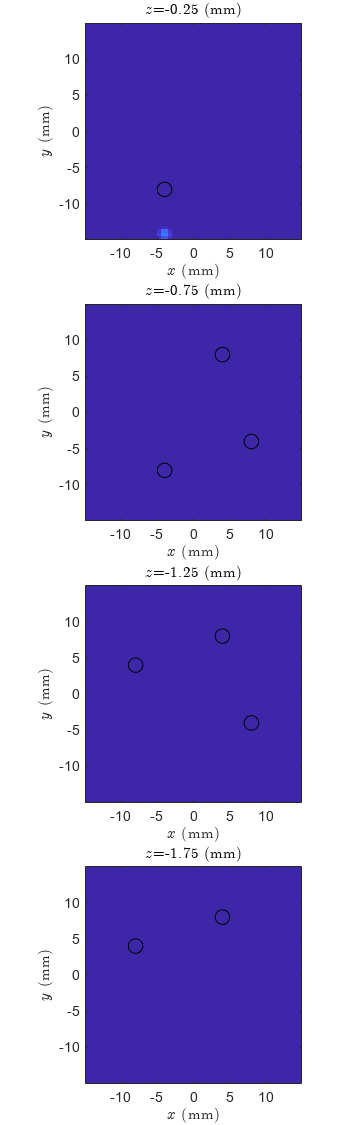

a = 0.0500

b = 0.3500

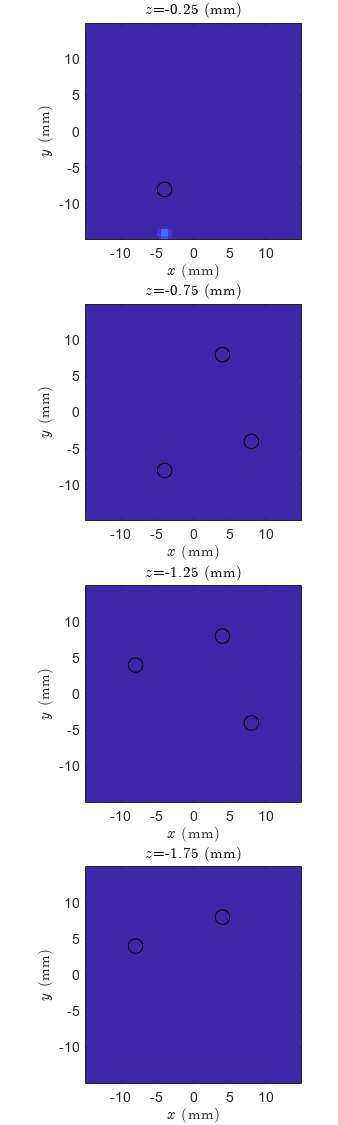

a = 0.0500

b = 0.4000

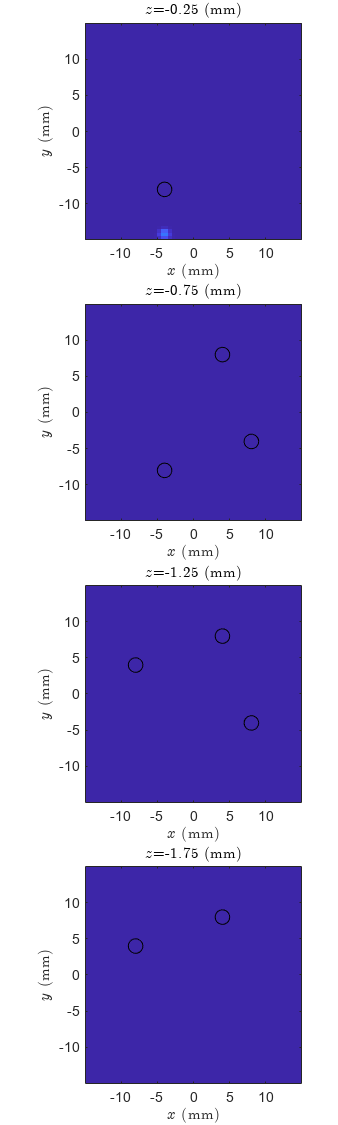

for a = 0.05:0.05:0.95
for b = 0.05:0.05:0.95
    if a >= b
        continue
    end
    z = binary_MF(Phi, y, 'a',a, 'b',b);

    a
    b
    displayReconstruction(z, voxels_center, defects)
    drawnow
end
end

function displayReconstruction(c, voxels_center, defects)

seperate = false;

z = unique(voxels_center(3,:));
z = sort(z, 'descend');

scale = 1e3;

if ~seperate
    figure
    tl = tiledlayout(length(z),1, 'TileSpacing','tight', 'Padding','none');
    set(gcf, 'Position',[10 10 flip(tl.GridSize) .* [300 250]])
end

for k = 1:length(z)
    mask = voxels_center(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    x = [min(voxels_center(1,mask)) max(voxels_center(1,mask))] * scale;
    y = [min(voxels_center(2,mask)) max(voxels_center(2,mask))] * scale;
    dx = (x(2) - x(1)) / size(c_layer,1);
    dy = (y(2) - y(1)) / size(c_layer,2);

    if ~seperate
        nexttile
    else
        figure('Position',[10 10 900 800])
        tiledlayout(1,1, 'TileSpacing','none', 'Padding','none')
        nexttile
    end

    imagesc(x, y, c_layer.', [0 1])
    axis square xy
    colormap sky
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlim(x + [-dx dx]/2)
    ylim(y + [-dy dy]/2)

    hold on
    for p = 1:length(defects)
        defect = defects{p};
        if ~(min(defect.z1, defect.z2) <= z(k) && z(k) <= max(defect.z1, defect.z2))
            continue
        end
        switch lower(defect.type)
            case 'rectangular'
                rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
                rectangle('Position', rect * scale)
            case 'circular'
                theta = linspace(0, 2*pi);
                x = defect.c_x + defect.d/2 * cos(theta);
                y = defect.c_y + defect.d/2 * sin(theta);
                plot(x * scale, y * scale, 'k')
            case 'polygonal'
                plot(defect.xs * scale, defect.ys * scale, 'k')
            otherwise
                error('Unknown defect shape "%s"', defect.type)
        end
    end
end

end